clc; clearvars;

load(".\chip4Audio19March\audioresponse_v1_repeat.mat");
load("TI46-IF.mat");

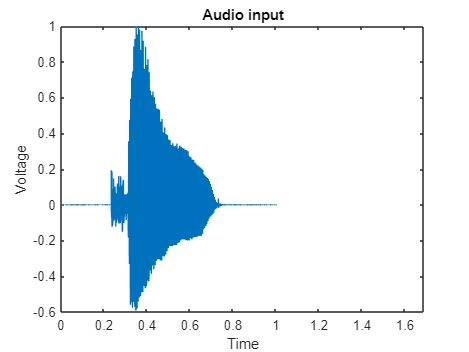


sampleID =3;
figure(1);
signal = DATA(sampleID).sig;
t = (1:length(signal))/12500;
plot(t,signal);
xlim([0 1.69]);
xlabel('Time');
ylabel('Voltage');
title('Audio input');

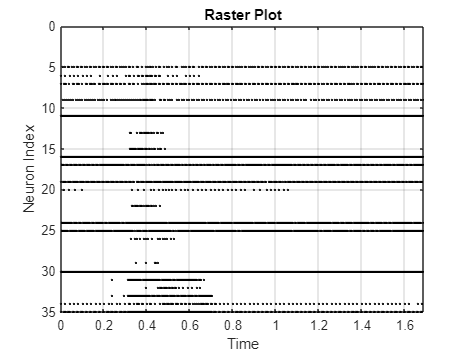

Received_data = SpikeResponse(sampleID).Response;
%% 
data = uint8(Received_data); % Ensure the data is in uint8
reshapedData = reshape(data, 8, []).';
% Convert the 4 uint8 numbers to uint32 considering the 4th byte as MSB
neuron_id = reshapedData(:, 1); % Extract the first byte
times = reshapedData(:, 5:end); % Extract the next 4 bytes
%%
%index_uint32 = zeros(size(neuron_id,1),1);
time_uint32 = zeros(size(times,1),1);
for i = 1:numel(neuron_id)
    %index_uint32(i) = typecast(uint8((indices(i,:))), 'uint32'); % Convert to uint32
    time_uint32(i) = typecast(uint8((times(i,:))), 'uint32'); % Convert to uint32
end
%%
time = 169984000-time_uint32;
%% 
figure(2); % Create a new figure
plot(time*1e-8, neuron_id, 'k.', 'MarkerSize', 5); % Raster plot using dots
% Formatting the plot
xlabel('Time');
ylabel('Neuron Index');
title('Raster Plot');

ylim([0 35]); % Set y-axis limits
%xlim([5/5000 15/5000])
xlim([0 1.69])
set(gca, 'YDir', 'reverse'); % Optional: Invert y-axis to align with convention
grid on;